## Final Project Pre-Quiz: Watching the RoadTraffic.mp4 video

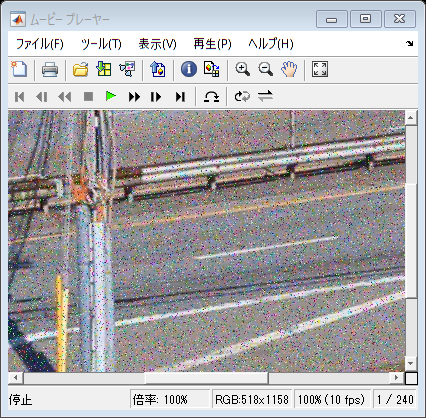

videoFullPath = "../../Data/Data/MathWorks Images/RoadTraffic.mp4";
implay(videoFullPath)

v = VideoReader(videoFullPath)

v =   VideoReader のプロパティ:

   一般的なプロパティ:
            Name: 'RoadTraffic.mp4'
            Path: 'C:\Users\kenconnor\Desktop\playground_matlab\Image Processing for Engineering and Science\Data\Data\MathWorks Images'
        Duration: 24
     CurrentTime: 0.1000
       NumFrames: 240

   ビデオ プロパティ:
           Width: 1158
          Height: 518
       FrameRate: 10
    BitsPerPixel: 24
     VideoFormat: 'RGB24'


% Q1
v.NumFrames

ans = 240

% Q2
v.FrameRate

ans = 10

% Q3
v.Width*v.Height

ans = 599844

## Section 1: Preprocessing the video

Removing noise from a video frame

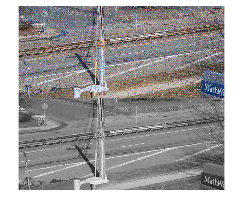

img = read(v,1);
montage({img,enhanceImg(img)})

write out new video

v = VideoReader(videoFullPath);
vOut = VideoWriter("RoadTrafficFiltered.mp4","MPEG-4");
vOut.FrameRate = v.FrameRate;
open(vOut);
for idx = 1:v.NumFrames
    frame = readFrame(v);
    for j = 1:3
        frame(:,:,j) = enhanceImg(frame(:,:,j));
    end
    writeVideo(vOut,frame);
end
close(vOut);

## Section 2: Isolating the cars

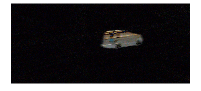

v = VideoReader("RoadTrafficFiltered.mp4");
idx = 22;
img = im2double(read(v,idx));
background = im2double(read(v,1));
imDiff = im2uint8(abs(img-background));
imshow(imDiff)

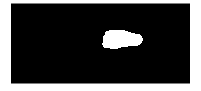

[bw,masked] = segmentCar(imDiff);
imshow(bw)

props = regionprops("table",bw);
height(props)

ans = 1

props.Area

ans = 25291

create a video

background = read(v,1);
v.CurrentTime = 0;
background = im2double(background);
vOut = VideoWriter("vout.mp4","MPEG-4");
vOut.FrameRate = v.FrameRate;
open(vOut);
for i=1:v.NumFrames
    img = readFrame(v);
    img = im2double(img);
    imDiff = im2uint8(abs(img-background));
    [bw,maskedImg] = segmentCar(imDiff);
    frameOut = im2uint8(img);
    frameOut(repmat(bw,[1,1,3])==0) = 0;
    writeVideo(vOut,frameOut);
end
close(vOut);

## Section 3: Calculating region properties

background = im2double(read(v,1));
v.CurrentTime = 0;
NumberRegions = [];
MeanRegionSize = [];
TotalRegionSize = [];
for idx = 1:v.NumFrames
    img = im2double(read(v,idx));
    imDiff = im2uint8(abs(img-background));
    bw = segmentCar(imDiff);
    props = regionprops("table",bw,"Area");
    NumberRegions = [NumberRegions; height(props)];
    sumRegions = 0;
    for i = 1:height(props)
        sumRegions = sumRegions + props.Area(i);
    end
    TotalRegionSize = [TotalRegionSize; sumRegions];
    if height(props) ~= 0
        meanRegion = round(sumRegions/height(props));
    else
        meanRegion = 0;
    end
    MeanRegionSize = [MeanRegionSize; meanRegion];
end
carData = table(NumberRegions,MeanRegionSize,TotalRegionSize);

answers followed

% Q1
nnz(carData.NumberRegions)

ans = 149

% Q2
carData.TotalRegionSize(152)

ans = 61549

% Q3
mode(carData.NumberRegions)

ans = 1

% Q4
% round(mean(carData.MeanRegionSize))
round(sum(carData.TotalRegionSize)/sum(carData.NumberRegions))

ans = 15301

% Q5

Q5. 

Sometimes a car splits.It occurs when a car approaches pillow.

## Final Challenge

v = VideoReader("RoadTrafficFiltered.mp4");
vOut = VideoWriter("RoadTrafficCount.mp4","MPEG-4");
vOut.FrameRate = v.FrameRate;
open(vOut);
for idx=1:v.NumFrames
    img = im2double(read(v,idx));
    imDiff = im2uint8(abs(img-background));
    bw = segmentCar(imDiff);
    props = regionprops("table",bw,"BoundingBox");
    numCars = height(props);
    if numCars~=0
        img = insertShape(img,"rectangle",props.BoundingBox,"Color","red","LineWidth",5);
    end
    textPos = [50 v.Height-50];
    img = insertText(img,textPos,"Num of Cars: "+string(numCars));
    writeVideo(vOut,img);
end
close(vOut);

play the video you created

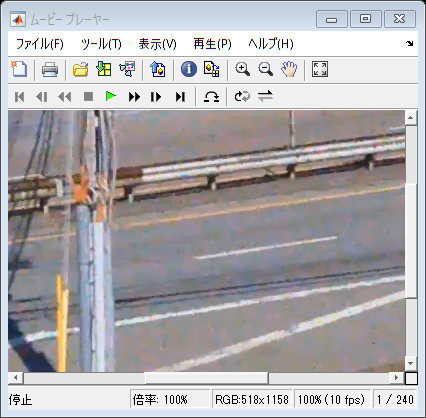

implay("./Final.mp4")

function [BW,maskedImage] = segmentCar(RGB)
% RGB イメージを L*a*b* 色空間に変換します。
% X = rgb2lab(RGB);
X = RGB;

% 空のマスクを作成
BW = false(size(X,1),size(X,2));

% イメージのしきい値処理 - 手動しきい値
BW = im2gray(X) > 3.472000e+01;

% line によるマスクのクローズ
length = 40.000000;
angle = 0.000000;
se = strel('line', length, angle);
BW = imclose(BW, se);

% disk によるマスクのクローズ
radius = 3;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imclose(BW, se);

% disk によるマスクのオープン
radius = 25;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imopen(BW, se);

% Create masked image.
maskedImage = RGB;
maskedImage(repmat(~BW,[1 1 3])) = 0;
end


function img = enhanceImg(img)

% for i=1:3
%     img(:,:,i) = medfilt2(img(:,:,i));
% end
% img = im2gray(img);
img = medfilt2(im2gray(img));

end